clear all

## Problem a

% System time (characteristic time)
t0 = 0;
tf = 8;
time = linspace(t0,tf,10000);

% Planet Initializing
aEarth = 1; % semimajor axis, AU
vEarth = 0; % true anomaly, rad
aMars = 1.524; % semimajor axis, AU
vMars = pi; % true anomaly, rad
mu = 1; % using characteristic time and length

% Planetary motion
velEarth = sqrt(mu / aEarth^3); % angular velocity
velMars = sqrt(mu / aMars^3); % angular velocity
posEarth = @(t) aEarth * [cos(vEarth + velEarth*t), sin(vEarth + velEarth*t)].'; % propagate earth
posMars = @(t) aMars * [cos(vMars + velMars*t), sin(vMars + velMars*t)].'; % propagate mars

% Spacecraft initializing
r0 = [aEarth, 0].'; % initial position
v0 = [0, aEarth * velEarth].'; % initial velocity

lamd0Init = zeros(4,1); % initialize costate vector
%lamd0Init = [1.4451;1.3013;6.4763;-7.4780];

% Define ODE
function XDot = spacecraftODE(t, X)
    mu = 1;
    r = X(1:2); % position
    v = X(3:4); % velocity
    
    lamdr = X(5:6); % position costate
    lamdv = X(7:8); % velocity costate

    u = -1/2 * lamdv; % OPTIMAL CONTROL EQUATION

    rDot = v; % derivative r
    vDot = -mu * r / norm(r)^3 + u; % derivative v

    lamdrDot = -mu * ((3*(r*r')/norm(r)^5 - eye(2)/norm(r)^3) * lamdv); % derivative pos costate
    lamdvDot = -lamdr; % derivative vel costate

    XDot = [rDot; vDot; lamdrDot; lamdvDot]; % STATE ODE
end

% Define SHOOTING FUNCTION
function residual = shooting(lamd0, posMars, t0, tf, r0, v0, velMars)
    X0 = [r0; v0; lamd0]; % initial state
    tSpan = linspace(t0,tf,10000); % time span
    options = odeset('RelTol', 1e-12, 'AbsTol', 1e-12);
    [~, X] = ode45(@spacecraftODE, tSpan, X0, options); % ODE solver
    rf = X(end, 1:2).'; % FINAL position
    vf = X(end, 3:4).'; % Final velocity

    posMarsf = posMars(tf);
    velMarsf = velMars * [-posMarsf(2); posMarsf(1)];

    residual = [rf - posMarsf; vf - velMarsf]; % difference between final position and Mars
end

% CALCULATE LAMBDA0
shot = @(lamd0) shooting(lamd0, posMars, t0, tf, r0, v0, velMars)

shot = function_handle with value:
    @(lamd0)shooting(lamd0,posMars,t0,tf,r0,v0,velMars)


options = optimoptions('fsolve', 'Display','iter','FunctionTolerance', 1e-8); % optimization options
lamd0Calc = fsolve(shot, lamd0Init, options) % CALCULATED INITIAL COSTATE VECTOR


                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          5             1.14247                             466              1
     1         10            0.119913      0.0896476             58.7              1
     2         11            0.119913       0.205029             58.7              1
     3         16           0.0558929      0.0512572             17.9         0.0513
     4         21           0.0461016       0.128143             65.3          0.128
     5         26         5.97145e-05      0.0184105             0.48          0.128
     6         31         2.69851e-09     0.00203466           0.0164          0.128
     7         36         6.89274e-19    1.30251e-06          1.3e-07          0.128

Equation solved.

fsolve completed because the vector of function values is n

lamd0Calc =     0.0843
    0.0095
    0.0196
    0.1077


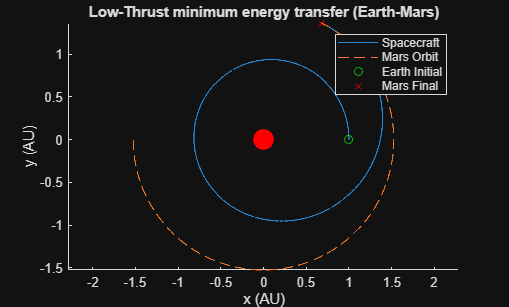


% Trajectory simulation
X0 = [r0; v0; lamd0Calc];
options = odeset('RelTol', 1e-12, 'AbsTol', 1e-12);
[~, X] = ode45(@spacecraftODE, time, X0, options);
rxt = X(:,1);
ryt = X(:,2);
posMarst = zeros(2, length(time));
for i = 1:length(time)
    posMarst(:,i) = posMars(time(i));
end

% Control Extraction
lamdvx = X(:,7);
lamdvy = X(:,8);
ux = -1/2 * lamdvx;
uy = -1/2 * lamdvy;
uMag = sqrt(ux.^2 + uy.^2);

% Costate Extraction
lamdrx = X(:,5);
lamdry = X(:,6);
lamdvx = X(:,7);
lamdvy = X(:,8);

% Hamiltonian Delta
H = zeros(length(time),1);
for i = 1:length(time)
    Hr = X(i,1:2)';
    Hv = X(i,3:4)';
    Hlamdr = X(i,5:6)';
    Hlamdv = X(i,7:8)';
    Hu = -1/2 * Hlamdv;
    H(i) = Hu'*Hu + Hlamdr'*Hv + Hlamdv'*(-mu*Hr/norm(Hr)^3 + Hu);
end
deltaH = H - H(1);

% PLOTS
figure
hold on
plot(rxt, ryt)
plot(posMarst(1,:), posMarst(2,:),'--', 'MarkerSize', 0.1)
plot(r0(1), r0(2), 'go', posMarst(1,end), posMarst(2,end), 'rx')
plot(0,0, 'ro', 'MarkerSize', 15, 'MarkerFaceColor','r')
axis equal
title("Low-Thrust minimum energy transfer (Earth-Mars)")
xlabel("x (AU)")
ylabel("y (AU)")
legend('Spacecraft', 'Mars Orbit', 'Earth Initial', 'Mars Final')
hold off

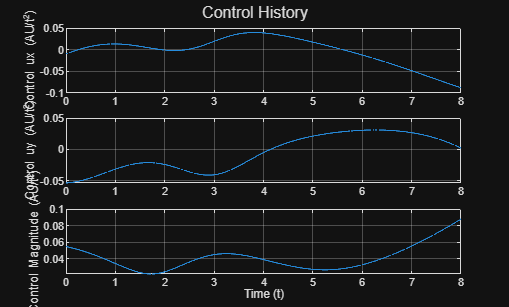


figure
hold on
subplot(3,1,1)
sgtitle("Control History")
plot(time,ux)
ylabel('Control ux (AU/t^2)')
grid on
subplot(3,1,2)
plot(time,uy)
ylabel('Control uy (AU/t^2)')
grid on
subplot(3,1,3)
plot(time, uMag)
ylabel('Control Magnitude (AU/t^2)')
xlabel('Time (t)')
grid on
hold off

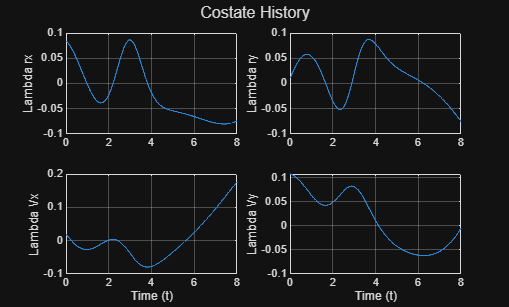


figure
hold on
sgtitle("Costate History")
subplot(2,2,1)
plot(time, lamdrx)
ylabel('Lambda rx')
grid on
subplot(2,2,2)
plot(time, lamdry)
ylabel('Lambda ry')
grid on
subplot(2,2,3)
plot(time, lamdvx)
ylabel('Lambda Vx')
grid on
xlabel('Time (t)')
subplot(2,2,4)
plot(time, lamdvy)
ylabel('Lambda Vy')
grid on
xlabel('Time (t)')
hold off

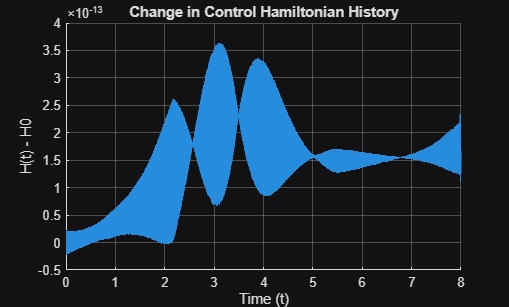


figure
hold on
plot(time,deltaH)
xlabel('Time (t)')
ylabel('H(t) - H0')
grid on
title("Change in Control Hamiltonian History")
hold off

## Different initial conditions

lamd0Correct = [];
lamd0Fail = [];
for N = 1:20
    lamd0Init = unifrnd(-10,10,4,1);
    try
        options = optimoptions('fsolve', 'display', 'iter', 'FunctionTolerance', 1e-8, 'MaxFunctionEvaluations', 500); % optimization options
        [lamd0Calc, ~, exitflag] = fsolve(shot, lamd0Init, options);
    catch
        lamd0Fail(:,end+1) = lamd0Init;
        continue
    end
        % Trajectory simulation
        X0 = [r0; v0; lamd0Calc];
        options = odeset('RelTol', 1e-12, 'AbsTol', 1e-12);
        [~, X] = ode45(@spacecraftODE, time, X0, options);
        rxt = X(:,1);
        ryt = X(:,2);
        posMarst = zeros(2, length(time));
        for i = 1:length(time)
            posMarst(:,i) = posMars(time(i));
        end
        
        % Control Extraction
        lamdvx = X(:,7);
        lamdvy = X(:,8);
        ux = -1/2 * lamdvx;
        uy = -1/2 * lamdvy;
        uMag = sqrt(ux.^2 + uy.^2);
        
        % Costate Extraction
        lamdrx = X(:,5);
        lamdry = X(:,6);
        lamdvx = X(:,7);
        lamdvy = X(:,8);
        
        % Hamiltonian Delta
        H = zeros(length(time),1);
        for i = 1:length(time)
            Hr = X(i,1:2)';
            Hv = X(i,3:4)';
            Hlamdr = X(i,5:6)';
            Hlamdv = X(i,7:8)';
            Hu = -1/2 * Hlamdv;
            H(i) = Hu'*Hu + Hlamdr'*Hv + Hlamdv'*(-mu*Hr/norm(Hr)^3 + Hu);
        end
        deltaH = H - H(1);
        threshold = 1;
        aboveThresh = any(abs(deltaH) > threshold);

        if (exitflag > 0) && (aboveThresh == 0)
            lamd0Correct(:,end+1) = lamd0Init;
        else
            lamd0Fail(:,end+1) = lamd0Init;
        end
end


                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          5              164636                        1.45e+04              1
     1         10              128401              1         1.23e+04              1
     2         15             59112.9            2.5         7.78e+03            2.5
     3         20             1685.27           6.25         1.87e+03           6.25
     4         25             998.378        4.90451         2.98e+03           15.6
     5         30             165.927         2.6134              543           15.6
     6         35             12.7705        1.35903             70.9           15.6
     7         40             1.04297       0.290434              215           15.6
     8         45            0.374529         0.6846             57.3           15.6
     9         50            0.067416       0.199701            


lamd0Correct
lamd0Fail